### 13/03/25 @ 15-34-17, Probe Power: -42dBm Pump Power: -10dBm, 2.6531 GHz Transition

clc
clear all

vari = {"vna_f0", "vna_f1", "vna_ifbw","vna_npoints", "vna_pow","xx", "yy", "zz", "zzph", "n_zz", "n_zzph", "bg_PH", "bg_RF"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\mw_time_spectrum_r19s2_nat_Er_CWO_2654_MHz_-10dBm_7mK__13-Mar-2025_@_15-34-17\mw_time_spectrum_r19s2_nat_Er_CWO_2654_MHz_-10dBm_7mK__@15-34-17.mat', vari{:})

table({strcat(num2str(vna_f0/1e9),'-',num2str(vna_f1/1e9), 'GHz')}, {num2str(vna_npoints)}, 'VariableNames',{'Probe range','VNA points'})

ans = 1×2 table
       Probe range        VNA points
    __________________    __________

    {'2.646-2.662GHz'}     {'201'}  


table({strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_npoints)},{duration(seconds(xx(end)), 'Format', 'hh:mm:ss')},'VariableNames',{'IFBW','Time steps','Duration'})

ans = 1×3 table
       IFBW       Time steps      Duration  
    __________    __________    ____________

    {'200 Hz'}     {'201'}      {[01:25:17]}


**Plot Transmission and Phase**

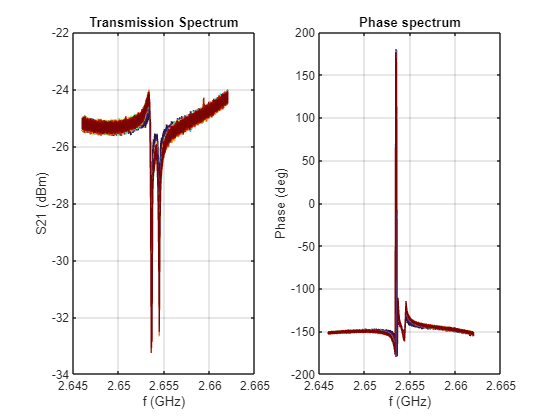


%Plots raw transmission and phase at the probe range
cc = turbo(size(zz,2));
freq = yy/1e9;
fr_idx = find(freq == 2.6536);

figure; 

for i = 1:size(zz,2)
    subplot(1,2,1)
    plot(freq, zz(:,i), 'Color',cc(i,:))
    hold on
    grid on
end
title('Transmission Spectrum')
xlabel('f (GHz)')
ylabel('S21 (dBm)')

for i = 1:size(zz,2)
    subplot(1,2,2)
    plot(freq, zzph(:,i), 'Color',cc(i,:))
    hold on
    grid on
end

title('Phase spectrum')
xlabel('f (GHz)')
ylabel('Phase (deg)')

**S21 Decay**

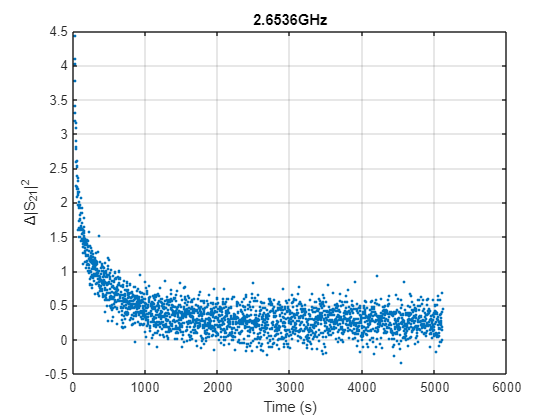

%Normalize S21
fr_idx = find(freq == 2.6536);

figure;
plot(xx, smoothdata(n_zz(fr_idx, :), 'movmean', 1), '.')
grid on
xlabel('Time (s)')
ylabel('\Delta|S_{21}|^2')
title(strcat(num2str(freq(fr_idx)), 'GHz'))

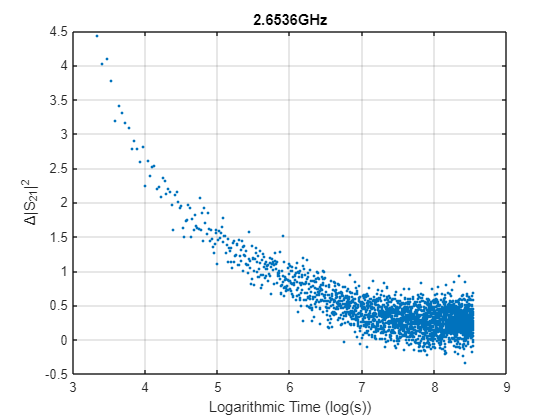


figure
plot(log(xx), smoothdata(n_zz(fr_idx, :), 'movmean', 1), '.')
grid on
xlabel('Logarithmic Time (log(s))')
ylabel('\Delta|S_{21}|^2')
title(strcat(num2str(freq(fr_idx)), 'GHz'))

#### **Two term exponential Fitting**

mag_fr = n_zz(fr_idx, :);

fit_obj = fit(xx', mag_fr', 'exp2');
fit_params = coeffvalues(fit_obj)

fit_params =     2.7790   -0.0056    0.4933   -0.0002


params = coeffnames(fit_obj)

params = 4×1 cell array
    {'a'}
    {'b'}
    {'c'}
    {'d'}


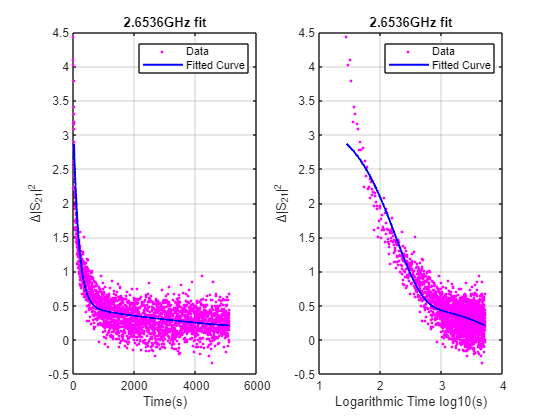



figure;

subplot(1,2,1)
plot((xx), mag_fr, 'm.');
hold on;
grid on;
plot((xx), fit_obj(xx), 'blue', 'LineWidth', 1.5);
xlabel( 'Time(s)' );
ylabel( '\Delta|S_{21}|^2');
title(strcat(num2str(freq(fr_idx)), 'GHz fit'))
legend('Data', 'Fitted Curve')

subplot(1,2,2)
plot(log10(xx), mag_fr, 'm.');
hold on;
grid on;
plot(log10(xx), fit_obj(xx), 'blue', 'LineWidth', 1.5);
xlabel( 'Logarithmic Time log10(s)' );
ylabel( '\Delta|S_{21}|^2');
title(strcat(num2str(freq(fr_idx)), 'GHz fit'))
legend('Data', 'Fitted Curve')




table({num2str(fit_params(1))}, {num2str(-1/fit_params(2))}, {num2str(fit_params(3))}, {num2str(-1/fit_params(4))}, ...
'VariableNames', {'a', 't1', 'c', 't2'})

ans = 1×4 table
        a             t1              c              t2      
    _________    ____________    ___________    _____________

    {'2.779'}    {'179.8579'}    {'0.49328'}    {'5924.1122'}


#### Triple Exponential Fitting


fitfunc = fittype('a*exp(-x/t1) + b*exp(-x/t2) + c*exp(-x/t3)');

%fit
%Start Points

x0 = [max(mag_fr)-min(mag_fr) max(mag_fr)-min(mag_fr) max(mag_fr)-min(mag_fr) 5 5 5];
lbound = [min(mag_fr) min(mag_fr) min(mag_fr) 0 0 0]

lbound =    -0.3334   -0.3334   -0.3334         0         0         0


ubound = [2*max(mag_fr) 2*max(mag_fr) 2*max(mag_fr) 10000 10000 10000]

ubound = 1.0e+04 *

    0.0009    0.0009    0.0009    1.0000    1.0000    1.0000



[fit_obj3, gof] = fit(xx', mag_fr', fitfunc, 'StartPoint', x0, 'Lower', lbound, 'Upper', ubound);
fit_params3 = coeffvalues(fit_obj3)

fit_params3 = 1.0e+03 *

    0.0004    0.0068    0.0016    9.9625    0.0263    0.3530


params3 = coeffnames(fit_obj3)

params3 = 6×1 cell array
    {'a' }
    {'b' }
    {'c' }
    {'t1'}
    {'t2'}
    {'t3'}


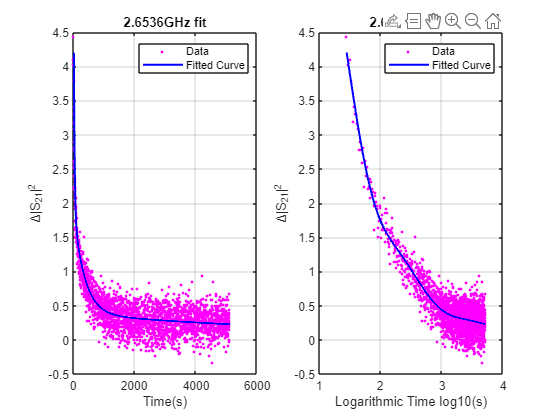


figure;
subplot(1,2,1)
plot((xx), mag_fr, 'm.');
hold on;
grid on;
plot((xx), fit_obj3(xx), 'blue', 'LineWidth', 1.5);
xlabel( 'Time(s)' );
ylabel( '\Delta|S_{21}|^2');
title(strcat(num2str(freq(fr_idx)), 'GHz fit'))
legend('Data', 'Fitted Curve')

subplot(1,2,2)
plot(log10(xx), mag_fr, 'm.');
hold on;
grid on;
plot(log10(xx), fit_obj3(xx), 'blue', 'LineWidth', 1.5);
xlabel( 'Logarithmic Time log10(s)' );
ylabel( '\Delta|S_{21}|^2');
title(strcat(num2str(freq(fr_idx)), 'GHz fit'))
legend('Data', 'Fitted Curve')


table({num2str(fit_params3(1))}, {num2str(fit_params3(2))}, {num2str(fit_params3(3))}, ...
    {num2str(fit_params3(4))},{num2str(fit_params3(5))}, {num2str(fit_params3(6))}, ...
'VariableNames', {'a', 'b', 'c', 't1', 't2', 't3'})

ans = 1×6 table
        a             b             c              t1              t2             t3     
    __________    __________    __________    _____________    __________    ____________

    {'0.3796'}    {'6.8222'}    {'1.6168'}    {'9962.5162'}    {'26.312'}    {'353.0295'}


#### Quadruple Exponential Fitting

fitfunc4 = fittype('a*exp(-x/t1) + b*exp(-x/t2) + c*exp(-x/t3) + d*exp(-x/t4)');

%define fit
%define start parameters and bounds

x0 = [max(mag_fr)-min(mag_fr) max(mag_fr)-min(mag_fr) max(mag_fr)-min(mag_fr) max(mag_fr)-min(mag_fr) 5 5 5 5];
lbound4 = [min(mag_fr) min(mag_fr) min(mag_fr) min(mag_fr) 0 0 0 0];
ubound4 = [max(mag_fr) max(mag_fr) max(mag_fr) max(mag_fr) 1e4 1e4 1e4 1e4];

[fitobj4, gof] = fit(xx', mag_fr',fitfunc4, 'StartPoint', x0, 'Lower', lbound4, 'Upper', ubound4);
fit_params4 = coeffvalues(fitobj4);
params4 = coeffnames(fitobj4);

figure;
subplot(1,2,1)
plot((xx), mag_fr, 'm.');
hold on;
grid on;
plot((xx), fit_obj4(xx), 'blue', 'LineWidth', 1.5);
xlabel( 'Time(s)' );
ylabel( '\Delta|S_{21}|^2');
title(strcat(num2str(freq(fr_idx)), 'GHz fit'))
legend('Data', 'Fitted Curve')

subplot(1,2,2)
plot(log10(xx), mag_fr, 'm.');
hold on;
grid on;
plot(log10(xx), fit_obj4(xx), 'blue', 'LineWidth', 1.5);
xlabel( 'Logarithmic Time log10(s)' );
ylabel( '\Delta|S_{21}|^2');
title(strcat(num2str(freq(fr_idx)), 'GHz fit'))
legend('Data', 'Fitted Curve')

table({num2str(fit_params4(1))}, {num2str(fit_params4(2))}, {num2str(fit_params4(3))}, ...
    {num2str(fit_params4(4))},{num2str(fit_params4(5))}, {num2str(fit_params4(6))},{num2str(fit_params4(7))}, {num2str(fit_params4(8))},...
'VariableNames', {'a', 'b', 'c','d', 't1', 't2', 't3', 't4'});

### 3.216 GHz Transition

clc
clear all

vari = {"vna_f0", "vna_f1", "vna_ifbw","vna_npoints", "vna_pow","xx", "yy", "zz", "zzph", "n_zz", "n_zzph", "bg_PH", "bg_RF"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\mw_time_spectrum_r19s2_nat_Er_CWO_3220_MHz_-10dBm_7mK__14-Mar-2025_@_15-32-40\mw_time_spectrum_r19s2_nat_Er_CWO_3220_MHz_-10dBm_7mK__@15-32-40.mat', vari{:})

table({strcat(num2str(vna_f0/1e9),'-',num2str(vna_f1/1e9), 'GHz')}, {num2str(vna_npoints)}, 'VariableNames',{'Probe range','VNA points'})

ans = 1×2 table
      Probe range       VNA points
    ________________    __________

    {'3.21-3.23GHz'}     {'201'}  


table({strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_npoints)},{duration(seconds(xx(end)), 'Format', 'hh:mm:ss')},'VariableNames',{'IFBW','Time steps','Duration'})

ans = 1×3 table
       IFBW       Time steps      Duration  
    __________    __________    ____________

    {'200 Hz'}     {'201'}      {[01:24:32]}


**Plot Transmission and Phase**

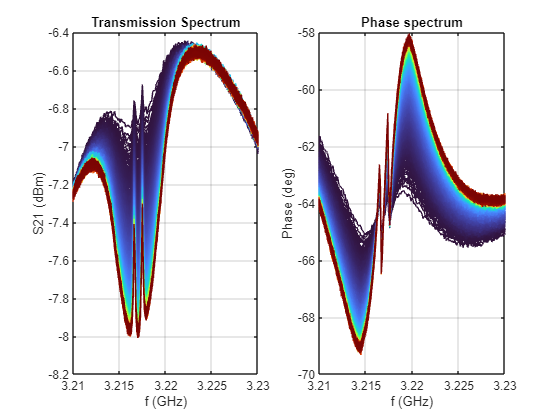

%Plots raw transmission and phase at the probe range
cc = turbo(size(zz,2));
freq = yy/1e9;
figure; 

for i = 1:size(zz,2)
    subplot(1,2,1)
    plot(freq, zz(:,i), 'Color',cc(i,:));
    hold on
    grid on
end
title('Transmission Spectrum')
xlabel('f (GHz)')
ylabel('S21 (dBm)')

for i = 1:size(zz,2)
    subplot(1,2,2)
    plot(freq, zzph(:,i), 'Color',cc(i,:));
    hold on
    grid on
end

title('Phase spectrum')
xlabel('f (GHz)')
ylabel('Phase (deg)')

**S21 Decay**

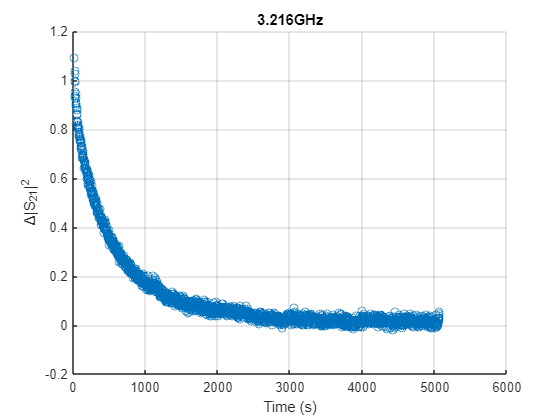

%Normalize S21
fr_idx = find(freq == 3.216);

figure;
scatter(xx, smoothdata(n_zz(fr_idx, :), 'movmean', 1))
grid on
xlabel('Time (s)')
ylabel('\Delta|S_{21}|^2')
title(strcat(num2str(freq(fr_idx)), 'GHz'))

**Two term exponential Fitting**

mag_fr = n_zz(fr_idx, :);

fit_obj = fit(xx', mag_fr', 'exp2');
fit_params = coeffvalues(fit_obj)

fit_params =     0.6663   -0.0030    0.3173   -0.0008


params = coeffnames(fit_obj)

params = 4×1 cell array
    {'a'}
    {'b'}
    {'c'}
    {'d'}


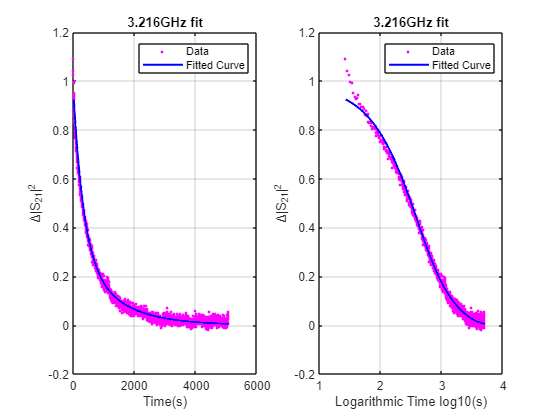



figure;

subplot(1,2,1)
plot((xx), mag_fr, 'm.');
hold on;
grid on;
plot((xx), fit_obj(xx), 'blue', 'LineWidth', 1.5);
xlabel( 'Time(s)' );
ylabel( '\Delta|S_{21}|^2');
title(strcat(num2str(freq(fr_idx)), 'GHz fit'))
legend('Data', 'Fitted Curve')

subplot(1,2,2)
plot(log10(xx), mag_fr, 'm.');
hold on;
grid on;
plot(log10(xx), fit_obj(xx), 'blue', 'LineWidth', 1.5);
xlabel( 'Logarithmic Time log10(s)' );
ylabel( '\Delta|S_{21}|^2');
title(strcat(num2str(freq(fr_idx)), 'GHz fit'))
legend('Data', 'Fitted Curve')




table({num2str(fit_params(1))}, {num2str(-1/fit_params(2))}, {num2str(fit_params(3))}, {num2str(-1/fit_params(4))}, ...
'VariableNames', {'a', 't1', 'c', 't2'})

ans = 1×4 table
         a              t1              c              t2      
    ___________    ____________    ___________    _____________

    {'0.66631'}    {'331.4839'}    {'0.31726'}    {'1240.3882'}


#### Triple Exponential Fitting


fitfunc = fittype('a*exp(-x/t1) + b*exp(-x/t2) + c*exp(-x/t3)');

%fit
%Start Points

x0 = [max(mag_fr)-min(mag_fr) max(mag_fr)-min(mag_fr) max(mag_fr)-min(mag_fr) 5 5 5];
lbound = [min(mag_fr) min(mag_fr) min(mag_fr) 0 0 0]

lbound =    -0.0184   -0.0184   -0.0184         0         0         0


ubound = [2*max(mag_fr) 2*max(mag_fr) 2*max(mag_fr) 10000 10000 10000]

ubound = 1.0e+04 *

    0.0002    0.0002    0.0002    1.0000    1.0000    1.0000



[fit_obj3, gof] = fit(xx', mag_fr', fitfunc, 'StartPoint', x0, 'Lower', lbound, 'Upper', ubound);
fit_params3 = coeffvalues(fit_obj3)

fit_params3 = 1.0e+03 *

    0.0005    0.0007    0.0002    0.0307    0.4601    1.7766


params3 = coeffnames(fit_obj3)

params3 = 6×1 cell array
    {'a' }
    {'b' }
    {'c' }
    {'t1'}
    {'t2'}
    {'t3'}


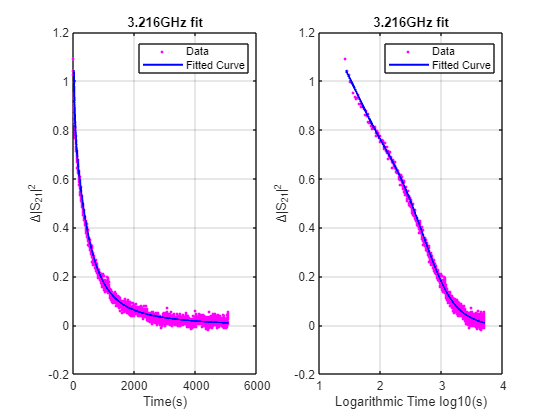


figure;
subplot(1,2,1)
plot((xx), mag_fr, 'm.');
hold on;
grid on;
plot((xx), fit_obj3(xx), 'blue', 'LineWidth', 1.5);
xlabel( 'Time(s)' );
ylabel( '\Delta|S_{21}|^2');
title(strcat(num2str(freq(fr_idx)), 'GHz fit'))
legend('Data', 'Fitted Curve')

subplot(1,2,2)
plot(log10(xx), mag_fr, 'm.');
hold on;
grid on;
plot(log10(xx), fit_obj3(xx), 'blue', 'LineWidth', 1.5);
xlabel( 'Logarithmic Time log10(s)' );
ylabel( '\Delta|S_{21}|^2');
title(strcat(num2str(freq(fr_idx)), 'GHz fit'))
legend('Data', 'Fitted Curve')


table({num2str(fit_params3(1))}, {num2str(fit_params3(2))}, {num2str(fit_params3(3))}, ...
    {num2str(fit_params3(4))},{num2str(fit_params3(5))}, {num2str(fit_params3(6))}, ...
'VariableNames', {'a', 'b', 'c', 't1', 't2', 't3'})

ans = 1×6 table
         a              b              c             t1              t2              t3      
    ___________    ___________    ___________    ___________    ____________    _____________

    {'0.47183'}    {'0.73449'}    {'0.15967'}    {'30.7459'}    {'460.1151'}    {'1776.6003'}


### 3.435 GHz Transition

clc
clear all

vari = {"vna_f0", "vna_f1", "vna_ifbw","vna_npoints", "vna_pow","xx", "yy", "zz", "zzph", "n_zz", "n_zzph", "bg_PH", "bg_RF"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\mw_time_spectrum_r19s2_nat_Er_CWO_3435_MHz_-10dBm_7mK_3.435GHzDecay_24-Mar-2025_@_11-13-11\mw_time_spectrum_r19s2_nat_Er_CWO_3435_MHz_-10dBm_7mK_3.435GHzDecay_@11-13-11.mat', vari{:})

table({strcat(num2str(vna_f0/1e9),'-',num2str(vna_f1/1e9), 'GHz')}, {num2str(vna_npoints)}, 'VariableNames',{'Probe range','VNA points'})

ans = 1×2 table
      Probe range       VNA points
    ________________    __________

    {'3.43-3.44GHz'}     {'201'}  


table({strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_npoints)},{duration(seconds(xx(end)), 'Format', 'hh:mm:ss')},'VariableNames',{'IFBW','Time steps','Duration'})

ans = 1×3 table
       IFBW       Time steps      Duration  
    __________    __________    ____________

    {'200 Hz'}     {'201'}      {[01:23:56]}


**Plot Transmission and Phase**

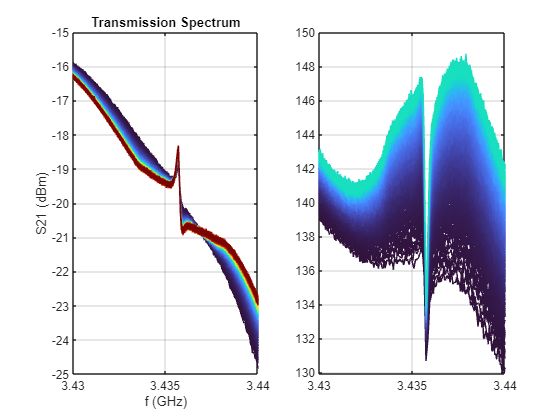

%Plots raw transmission and phase at the probe range
cc = turbo(size(zz,2));
freq = yy/1e9;
figure; 

for i = 1:size(zz,2)
    subplot(1,2,1)
    plot(freq, zz(:,i), 'Color',cc(i,:));
    hold on
    grid on
end
title('Transmission Spectrum')
xlabel('f (GHz)')
ylabel('S21 (dBm)')

for i = 1:size(zz,2)
    subplot(1,2,2)
    plot(freq, zzph(:,i), 'Color',cc(i,:));
    hold on
    grid on
end


title('Phase spectrum')
xlabel('f (GHz)')
ylabel('Phase (deg)')

**S21 Decay**

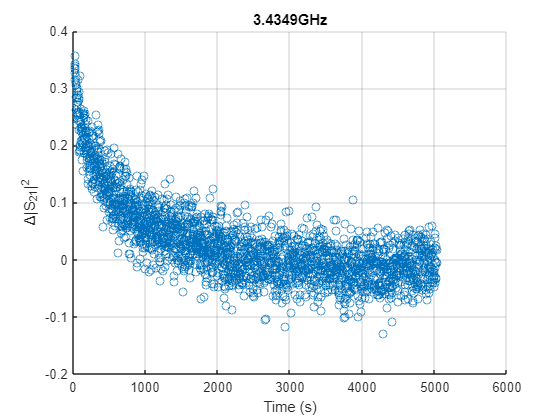

%Normalize S21
fr_idx = find(freq == 3.4349);

figure;
scatter(xx, smoothdata(n_zz(fr_idx, :), 'movmean', 1))
grid on
xlabel('Time (s)')
ylabel('\Delta|S_{21}|^2')
title(strcat(num2str(freq(fr_idx)), 'GHz'))

**Two term exponential Fitting**

mag_fr = n_zz(fr_idx, :);

fit_obj = fit(xx', mag_fr', 'exp2');
fit_params = coeffvalues(fit_obj)

fit_params =    -0.0027    0.0003    0.2772   -0.0014


params = coeffnames(fit_obj)

params = 4×1 cell array
    {'a'}
    {'b'}
    {'c'}
    {'d'}


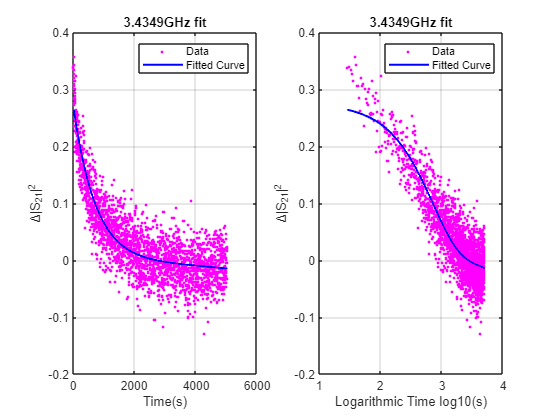



figure;

subplot(1,2,1)
plot((xx), mag_fr, 'm.');
hold on;
grid on;
plot((xx), fit_obj(xx), 'blue', 'LineWidth', 1.5);
xlabel( 'Time(s)' );
ylabel( '\Delta|S_{21}|^2');
title(strcat(num2str(freq(fr_idx)), 'GHz fit'))
legend('Data', 'Fitted Curve')

subplot(1,2,2)
plot(log10(xx), mag_fr, 'm.');
hold on;
grid on;
plot(log10(xx), fit_obj(xx), 'blue', 'LineWidth', 1.5);
xlabel( 'Logarithmic Time log10(s)' );
ylabel( '\Delta|S_{21}|^2');
title(strcat(num2str(freq(fr_idx)), 'GHz fit'))
legend('Data', 'Fitted Curve')




table({num2str(fit_params(1))}, {num2str(1/fit_params(2))}, {num2str(fit_params(3))}, {num2str(-1/fit_params(4))}, ...
'VariableNames', {'a', 't1', 'c', 't2'})

ans = 1×4 table
          a                t1               c              t2     
    ______________    _____________    ___________    ____________

    {'-0.0027394'}    {'2917.3118'}    {'0.27722'}    {'725.0511'}


#### Triple Exponential Fitting


fitfunc = fittype('a*exp(-x/t1) + b*exp(-x/t2) + c*exp(-x/t3)');

%fit
%Start Points

x0 = [max(mag_fr)-min(mag_fr) max(mag_fr)-min(mag_fr) max(mag_fr)-min(mag_fr) 5 5 5];
lbound = [min(mag_fr) min(mag_fr) min(mag_fr) 0 0 0]

lbound =    -0.1298   -0.1298   -0.1298         0         0         0


ubound = [2*max(mag_fr) 2*max(mag_fr) 2*max(mag_fr) 10000 10000 10000]

ubound = 1.0e+04 *

    0.0001    0.0001    0.0001    1.0000    1.0000    1.0000



[fit_obj3, gof] = fit(xx', mag_fr', fitfunc, 'StartPoint', x0, 'Lower', lbound, 'Upper', ubound);
fit_params3 = coeffvalues(fit_obj3)

fit_params3 =     0.1152    0.1417    0.1345  727.3744  719.5593   59.7851


params3 = coeffnames(fit_obj3)

params3 = 6×1 cell array
    {'a' }
    {'b' }
    {'c' }
    {'t1'}
    {'t2'}
    {'t3'}


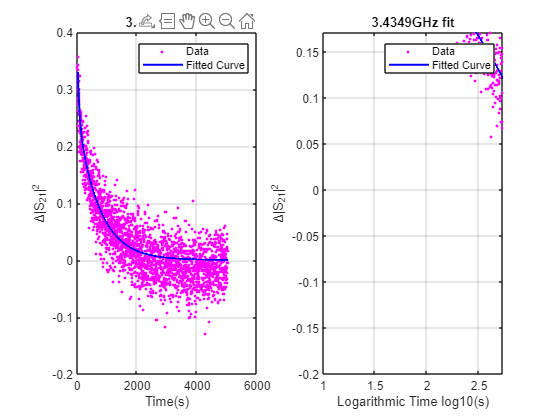


figure;
subplot(1,2,1)
plot((xx), mag_fr, 'm.');
hold on;
grid on;
plot((xx), fit_obj3(xx), 'blue', 'LineWidth', 1.5);
xlabel( 'Time(s)' );
ylabel( '\Delta|S_{21}|^2');
title(strcat(num2str(freq(fr_idx)), 'GHz fit'))
legend('Data', 'Fitted Curve')

subplot(1,2,2)
plot(log10(xx), mag_fr, 'm.');
hold on;
grid on;
plot(log10(xx), fit_obj3(xx), 'blue', 'LineWidth', 1.5);
xlabel( 'Logarithmic Time log10(s)' );
ylabel( '\Delta|S_{21}|^2');
title(strcat(num2str(freq(fr_idx)), 'GHz fit'))
legend('Data', 'Fitted Curve')


table({num2str(fit_params3(1))}, {num2str(fit_params3(2))}, {num2str(fit_params3(3))}, ...
    {num2str(fit_params3(4))},{num2str(fit_params3(5))}, {num2str(fit_params3(6))}, ...
'VariableNames', {'a', 'b', 'c', 't1', 't2', 't3'})

ans = 1×6 table
        a              b             c              t1              t2             t3     
    __________    ___________    __________    ____________    ____________    ___________

    {'0.1152'}    {'0.14174'}    {'0.1345'}    {'727.3744'}    {'719.5593'}    {'59.7851'}


### 2.6 GHz Transition 2nd Measurement

clc
clear all

vari = {"vna_f0", "vna_fc","vna_f1", "vna_ifbw","vna_npoints", "vna_pow","xx", "yy", "zz", "zzph", "n_zz", "n_zzph", "bg_PH", "bg_RF"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\mw_time_spectrum_r19s2_nat_Er_CWO_2654_MHz_-10dBm_7mK_2.6GHz_2ndMeas_09-Apr-2025_@_10-35-08\mw_time_spectrum_r19s2_nat_Er_CWO_2654_MHz_-10dBm_7mK_2.6GHz_2ndMeas_@10-35-08.mat', vari{:})

table({strcat(num2str(vna_f0/1e9),'-',num2str(vna_f1/1e9), 'GHz')}, {num2str(vna_npoints)}, 'VariableNames',{'Probe range','VNA points'})

ans = 1×2 table
       Probe range       VNA points
    _________________    __________

    {'2.65-2.658GHz'}     {'401'}  


table({strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_npoints)},{duration(seconds(xx(end)), 'Format', 'hh:mm:ss')},'VariableNames',{'IFBW','Time steps','Duration'})

ans = 1×3 table
       IFBW       Time steps      Duration  
    __________    __________    ____________

    {'200 Hz'}     {'401'}      {[02:37:37]}


**Plot Transmission and Phase**

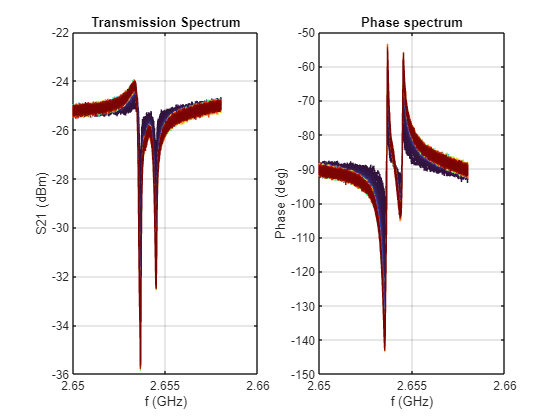

%Plots raw transmission and phase at the probe range
cc = turbo(size(zz,2));
freq = yy/1e9;
figure; 

for i = 1:size(zz,2)
    subplot(1,2,1)
    plot(freq, zz(:,i), 'Color',cc(i,:));
    hold on
    grid on
end
title('Transmission Spectrum')
xlabel('f (GHz)')
ylabel('S21 (dBm)')

for i = 1:size(zz,2)
    subplot(1,2,2)
    plot(freq, zzph(:,i), 'Color',cc(i,:));
    hold on
    grid on
end

title('Phase spectrum')
xlabel('f (GHz)')
ylabel('Phase (deg)')

**S21 Decay**

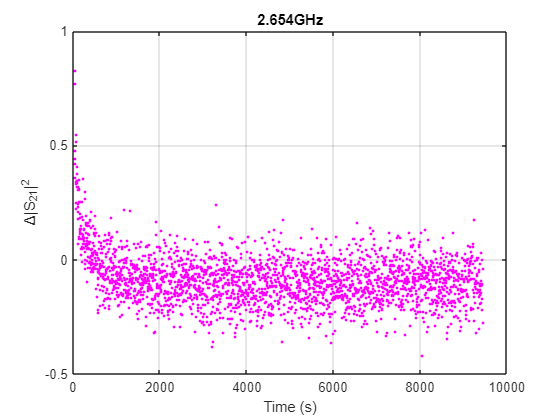

%Normalize S21
fr_idx = find(freq == vna_fc/1e9);

figure;
plot(xx, smoothdata(n_zz(fr_idx, :), 'movmean', 1), 'm.')
grid on
xlabel('Time (s)')
ylabel('\Delta|S_{21}|^2')
title(strcat(num2str(freq(fr_idx)), 'GHz'))

**Two term exponential Fitting**

mag_fr = n_zz(fr_idx, :);

fit_obj = fit(xx', mag_fr', 'exp2');
fit_params = coeffvalues(fit_obj)

fit_params =    -0.0948    0.0000    0.6108   -0.0037


params = coeffnames(fit_obj)

params = 4×1 cell array
    {'a'}
    {'b'}
    {'c'}
    {'d'}


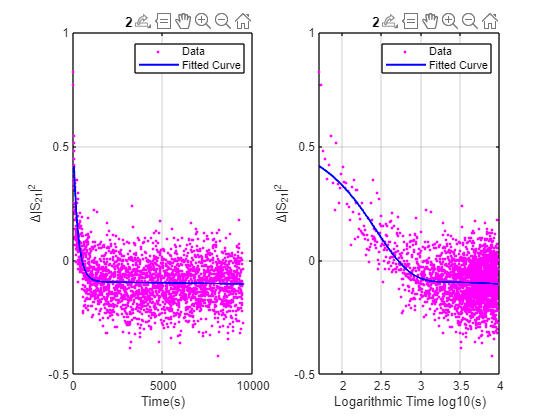



figure;

subplot(1,2,1)
plot((xx), mag_fr, 'm.');
hold on;
grid on;
plot((xx), fit_obj(xx), 'blue', 'LineWidth', 1.5);
xlabel( 'Time(s)' );
ylabel( '\Delta|S_{21}|^2');
title(strcat(num2str(freq(fr_idx)), 'GHz fit'))
legend('Data', 'Fitted Curve')

subplot(1,2,2)
plot(log10(xx), mag_fr, 'm.');
hold on;
grid on;
plot(log10(xx), fit_obj(xx), 'blue', 'LineWidth', 1.5);
xlabel( 'Logarithmic Time log10(s)' );
ylabel( '\Delta|S_{21}|^2');
title(strcat(num2str(freq(fr_idx)), 'GHz fit'))
legend('Data', 'Fitted Curve')




table({num2str(fit_params(1))}, {num2str(1/fit_params(2))}, {num2str(fit_params(3))}, {num2str(-1/fit_params(4))}, ...
'VariableNames', {'a', 't1', 'c', 't2'})

ans = 1×4 table
          a                t1               c              t2     
    _____________    ______________    ___________    ____________

    {'-0.094752'}    {'92608.0136'}    {'0.61077'}    {'268.3726'}


#### Triple Exponential Fitting


fitfunc = fittype('a*exp(-x/t1) + b*exp(-x/t2) + c*exp(-x/t3)');

%fit
%Start Points

x0 = [max(mag_fr)-min(mag_fr) max(mag_fr)-min(mag_fr) max(mag_fr)-min(mag_fr) 5 5 5];
lbound = [min(mag_fr) min(mag_fr) min(mag_fr) 0 0 0]

lbound =    -0.4192   -0.4192   -0.4192         0         0         0


ubound = [2*max(mag_fr) 2*max(mag_fr) 2*max(mag_fr) 10000 10000 10000]

ubound = 1.0e+04 *

    0.0002    0.0002    0.0002    1.0000    1.0000    1.0000



[fit_obj3, gof] = fit(xx', mag_fr', fitfunc, 'StartPoint', x0, 'Lower', lbound, 'Upper', ubound);
fit_params3 = coeffvalues(fit_obj3)

fit_params3 =     1.1052    0.3014    0.2830   30.9473  139.0882  138.1984


params3 = coeffnames(fit_obj3)

params3 = 6×1 cell array
    {'a' }
    {'b' }
    {'c' }
    {'t1'}
    {'t2'}
    {'t3'}


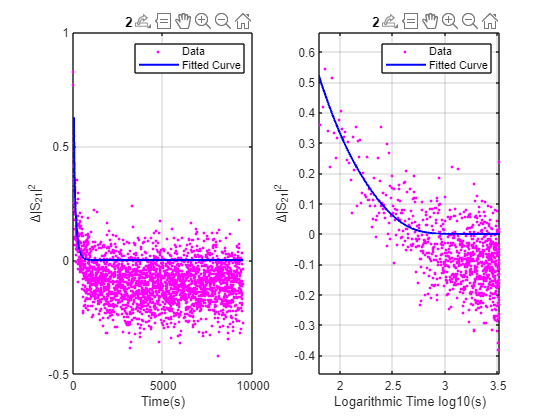


figure;
subplot(1,2,1)
plot((xx), mag_fr, 'm.');
hold on;
grid on;
plot((xx), fit_obj3(xx), 'blue', 'LineWidth', 1.5);
xlabel( 'Time(s)' );
ylabel( '\Delta|S_{21}|^2');
title(strcat(num2str(freq(fr_idx)), 'GHz fit'))
legend('Data', 'Fitted Curve')

subplot(1,2,2)
plot(log10(xx), mag_fr, 'm.');
hold on;
grid on;
plot(log10(xx), fit_obj3(xx), 'blue', 'LineWidth', 1.5);
xlabel( 'Logarithmic Time log10(s)' );
ylabel( '\Delta|S_{21}|^2');
title(strcat(num2str(freq(fr_idx)), 'GHz fit'))
legend('Data', 'Fitted Curve')


table({num2str(fit_params3(1))}, {num2str(fit_params3(2))}, {num2str(fit_params3(3))}, ...
    {num2str(fit_params3(4))},{num2str(fit_params3(5))}, {num2str(fit_params3(6))}, ...
'VariableNames', {'a', 'b', 'c', 't1', 't2', 't3'})

ans = 1×6 table
        a              b             c            t1              t2              t3     
    __________    ___________    _________    ___________    ____________    ____________

    {'1.1052'}    {'0.30136'}    {'0.283'}    {'30.9473'}    {'139.0882'}    {'138.1984'}


### 2.6 GHz Transition 3rd Measurement

clc
clear all

vari = {"vna_f0", "vna_fc","vna_f1", "vna_ifbw","vna_npoints", "vna_pow","xx", "yy", "zz", "zzph", "n_zz", "n_zzph", "bg_PH", "bg_RF"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\mw_time_spectrum_r19s2_nat_Er_CWO_2654_MHz_-10dBm_7mK_26_3rd_Decay_Meas_test_16-Apr-2025_@_13-24-18\mw_time_spectrum_r19s2_nat_Er_CWO_2654_MHz_-10dBm_7mK_26_3rd_Decay_Meas_test_@13-24-18.mat', vari{:})

table({strcat(num2str(vna_f0/1e9),'-',num2str(vna_f1/1e9), 'GHz')}, {num2str(vna_npoints)}, 'VariableNames',{'Probe range','VNA points'})

ans = 1×2 table
       Probe range       VNA points
    _________________    __________

    {'2.65-2.658GHz'}     {'201'}  


table({strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_npoints)},{duration(seconds(xx(end)), 'Format', 'hh:mm:ss')},'VariableNames',{'IFBW','Time steps','Duration'})

ans = 1×3 table
       IFBW       Time steps      Duration  
    __________    __________    ____________

    {'200 Hz'}     {'201'}      {[01:38:50]}


**Plot Transmission and Phase**

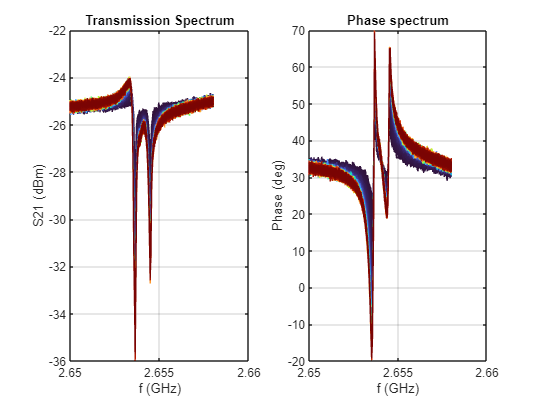

%Plots raw transmission and phase at the probe range
cc = turbo(size(zz,2));
freq = yy/1e9;
figure; 

for i = 1:size(zz,2)
    subplot(1,2,1)
    plot(freq, zz(:,i), 'Color',cc(i,:));
    hold on
    grid on; grid minor
end
title('Transmission Spectrum')
xlabel('f (GHz)')
ylabel('S21 (dBm)')

for i = 1:size(zz,2)
    subplot(1,2,2)
    plot(freq, zzph(:,i), 'Color',cc(i,:));
    hold on
    grid on; grid minor
end

title('Phase spectrum')
xlabel('f (GHz)')
ylabel('Phase (deg)')

**S21 Decay**

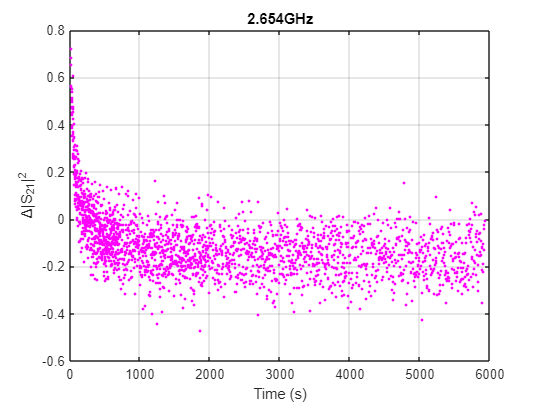

%Normalize S21
fr_idx = find(freq == vna_fc/1e9);

figure;
plot(xx, smoothdata(n_zz(fr_idx, :), 'movmean', 1), 'm.')
grid on
xlabel('Time (s)')
ylabel('\Delta|S_{21}|^2')
title(strcat(num2str(freq(fr_idx)), 'GHz'))

**Two term exponential Fitting**

mag_fr = n_zz(fr_idx, :);

fit_obj = fit(xx', mag_fr', 'exp2');
fit_params = coeffvalues(fit_obj)

fit_params =    -0.1151    0.0001    0.6679   -0.0073


params = coeffnames(fit_obj)

params = 4×1 cell array
    {'a'}
    {'b'}
    {'c'}
    {'d'}


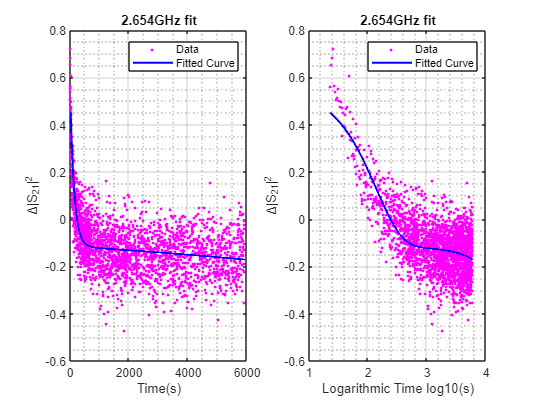



figure;

subplot(1,2,1)
plot((xx), mag_fr, 'm.');
hold on;
grid on; grid minor
plot((xx), fit_obj(xx), 'blue', 'LineWidth', 1.5);
xlabel( 'Time(s)' );
ylabel( '\Delta|S_{21}|^2');
title(strcat(num2str(freq(fr_idx)), 'GHz fit'))
legend('Data', 'Fitted Curve')

subplot(1,2,2)
plot(log10(xx), mag_fr, 'm.');
hold on;
grid on; grid minor
plot(log10(xx), fit_obj(xx), 'blue', 'LineWidth', 1.5);
xlabel( 'Logarithmic Time log10(s)' );
ylabel( '\Delta|S_{21}|^2');
title(strcat(num2str(freq(fr_idx)), 'GHz fit'))
legend('Data', 'Fitted Curve')




table({num2str(fit_params(1))}, {num2str(1/fit_params(2))}, {num2str(fit_params(3))}, {num2str(-1/fit_params(4))}, ...
'VariableNames', {'a', 't1', 'c', 't2'})

ans = 1×4 table
         a                t1               c              t2     
    ____________    ______________    ___________    ____________

    {'-0.11508'}    {'14937.7042'}    {'0.66786'}    {'137.6633'}


#### Triple Exponential Fitting


fitfunc = fittype('a*exp(-x/t1) + b*exp(-x/t2) + c*exp(-x/t3)');

%fit
%Start Points

x0 = [max(mag_fr)-min(mag_fr) max(mag_fr)-min(mag_fr) max(mag_fr)-min(mag_fr) 10 10 10];
lbound = [min(mag_fr) min(mag_fr) min(mag_fr) 0 0 0]

lbound =    -0.4705   -0.4705   -0.4705         0         0         0


ubound = [2*max(mag_fr) 2*max(mag_fr) 2*max(mag_fr) 10000 10000 10000]

ubound = 1.0e+04 *

    0.0001    0.0001    0.0001    1.0000    1.0000    1.0000



[fit_obj3, gof] = fit(xx', mag_fr', fitfunc, 'StartPoint', x0, 'Lower', lbound, 'Upper', ubound);
fit_params3 = coeffvalues(fit_obj3)

fit_params3 =     0.3402    0.5198    0.4918   57.2978   13.3924   57.1522


params3 = coeffnames(fit_obj3)

params3 = 6×1 cell array
    {'a' }
    {'b' }
    {'c' }
    {'t1'}
    {'t2'}
    {'t3'}


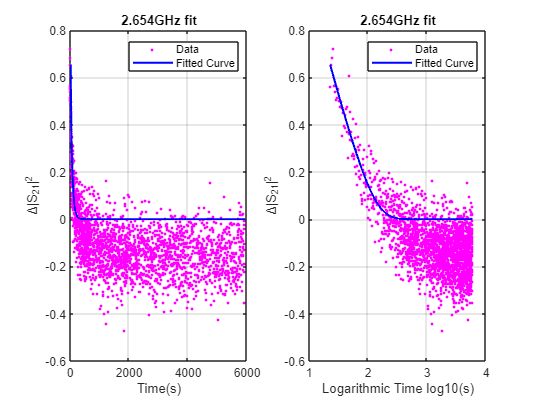


figure;
subplot(1,2,1)
plot((xx), mag_fr, 'm.');
hold on;
grid on;
plot((xx), fit_obj3(xx), 'blue', 'LineWidth', 1.5);
xlabel( 'Time(s)' );
ylabel( '\Delta|S_{21}|^2');
title(strcat(num2str(freq(fr_idx)), 'GHz fit'))
legend('Data', 'Fitted Curve')

subplot(1,2,2)
plot(log10(xx), mag_fr, 'm.');
hold on;
grid on;
plot(log10(xx), fit_obj3(xx), 'blue', 'LineWidth', 1.5);
xlabel( 'Logarithmic Time log10(s)' );
ylabel( '\Delta|S_{21}|^2');
title(strcat(num2str(freq(fr_idx)), 'GHz fit'))
legend('Data', 'Fitted Curve')


table({num2str(fit_params3(1))}, {num2str(fit_params3(2))}, {num2str(fit_params3(3))}, ...
    {num2str(fit_params3(4))},{num2str(fit_params3(5))}, {num2str(fit_params3(6))}, ...
'VariableNames', {'a', 'b', 'c', 't1', 't2', 't3'})

ans = 1×6 table
         a              b              c             t1             t2             t3     
    ___________    ___________    ___________    ___________    ___________    ___________

    {'0.34017'}    {'0.51977'}    {'0.49183'}    {'57.2978'}    {'13.3924'}    {'57.1522'}
